% формирование массива данных по Советску (обе станции)
clear

d = dir('C:\Users\user\MATLAB Drive\1Exponenta\01.03_train one GRS\data_sovetsk\data_sovetsk_united');

d(1:3) = []; % обнуление 

t5 = []; % создание пустого массива

for i = 1:numel(d)
    disp(i) % демо считывания данных по месяцам
    str = d(i).folder +"\"+ d(i).name; % считываем имя файла в директории d
    [a,txt] = readfile_all(str); % читаем файл, к которому обращаемся
    b = txt(3:end,2); % заменили формат, в котором указано время (часы), на читаемый 
    B = ismissing(b);% заменили формат, в котором указано время (часы), на читаемый 
    b(B) = [];% заменили формат, в котором указано время (часы), на читаемый 
    c = categorical(b);% заменили формат, в ктором указано время (часы), на читаемый 
    b1 = double(c);% заменили формат, в котором указано время (часы), на читаемый 
    t5 = [t5; [b1, a(:,1:5)]];% 
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12



b = t5(:,end) == 0;
B = diff(b);
f = find(B);
t5_1 = t5(1:f(1),:);
t5_2 = t5(f(end)+1:end,:);
idx_5_1 = f(1);
idx_5_2 = f(end)+1;

t5=[t5_1',t5_2'];
t5 = t5';

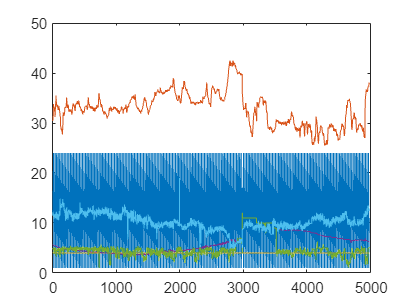

plot(t5);

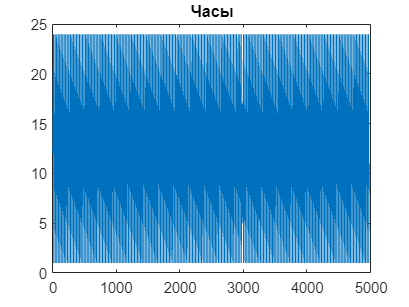

plot(t5(:,1));
title("Часы")

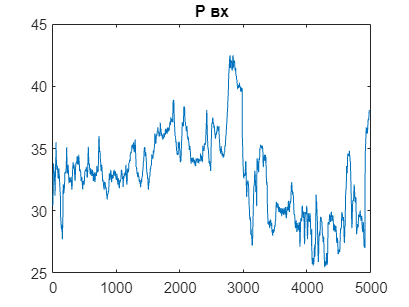

plot(t5(:,2));
title("P вх")

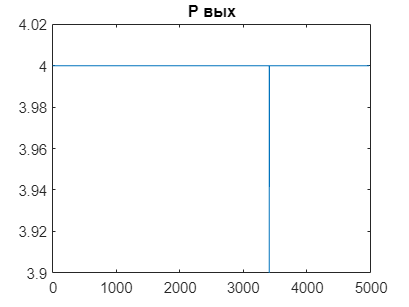

plot(t5(:,3));
title("P вых")

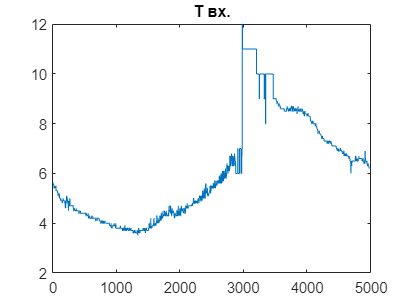

plot(t5(:,4));
title("Т вх.")

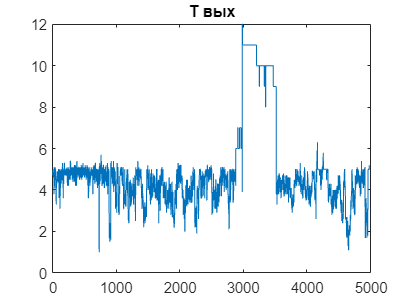

plot(t5(:,5));
title("Т вых")

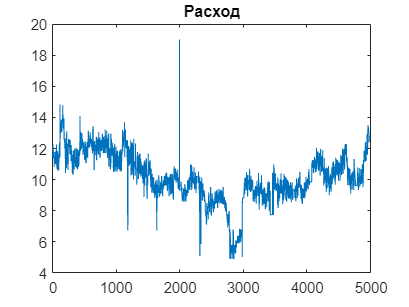

plot(t5(:,6));
title("Расход")

save data_sovetsk t5 t5_1 t5_2 idx_5_1 idx_5_2

function [t5,txt] = readfile_all(str)
[t5,txt] = xlsread(str,'Лист1');
s = all(isnan(t5));
t5(:,s) = [];
b = all(isnan(t5),2);
t5(b,:) = [];
end